v = VideoReader("liquidVideo.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'liquidVideo.mp4'
            Path: 'C:\Users\backupadmin\Documents\ImageProcessingCoursera\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 120
          Height: 216
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


v.FrameRate

ans = 10

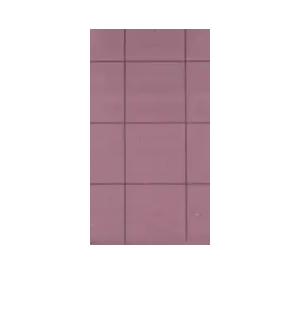

imshow(read(v,1)) %First Frame

%All the frames averaged together

frameSum = im2double(read(v,1));
for idx = 2:v.NumFrames
    frameSum = frameSum + im2double(read(v,idx));
end

aveFrame = frameSum/v.NumFrames;

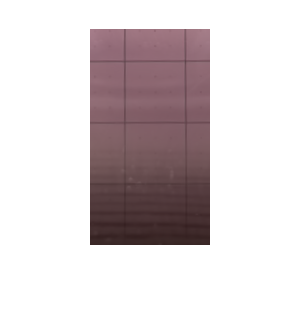

imshow(aveFrame)

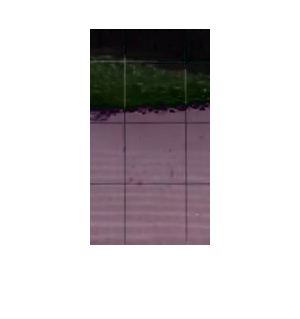

%Performing background substraction on frame 175, using 1st frame as bg

frame = read(v,175);
frame=im2double(frame);
background=im2double(read(v,1));
frameDiff =abs(frame-background);
imshow(frameDiff)

%Trying 3 different approaches for binary segmentation and morph

MorphedBW = sodaSegmenter(frameDiff);
nnz(MorphedBW)

ans = 16189

read(v,1)   

ans = 216×120×3 uint8 array
ans(:,:,1) =

   163   163   161   161   160   160   159   159   159   159   158   158   157   156   156   154   154   154   153   153   153   153   153   153   153   153   153   153   153   153   154   154   154   153   116   128   154   154   154   154   154   154   154   154   154   154   154   154   153   153   153   153   153   153   153   153   153   153   153   153   153   153   154   154   156   156   156   156   154   154   153   153   153   153   153   153   153   153   153   153   153   153   153   153   153   153   153   153   153   153   154   154   156   156   137   119   142   151   154   153   152   153   153   154   154   154   154   154   154   156   156   157   158   158   158   159   159   159   159   159
   163   163   161   161   160   160   159   159   159   159   158   158   157   156   156   154   154   154   153   153   153   153   153   153   153   153   153   153   153   153   154   154   154   153   116   128   154   154   154   

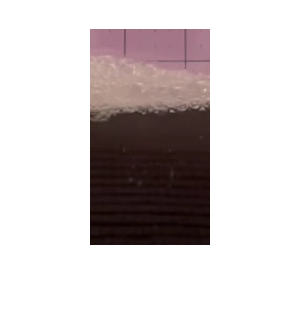

imshow(read(v,175))

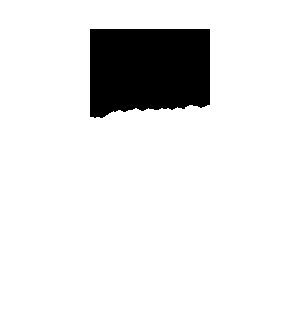

imshow(MorphedBW)

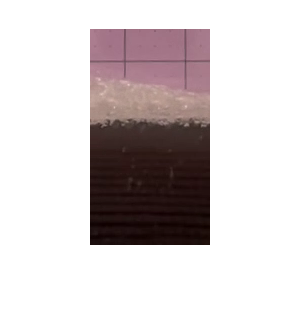

% Each frame is 216 pixel tall and 3.4 cm in height

% each pixel is 0.015cm in height

frame167 = read(v,167);
frame167 = im2double(frame167);
imshow(frame167)

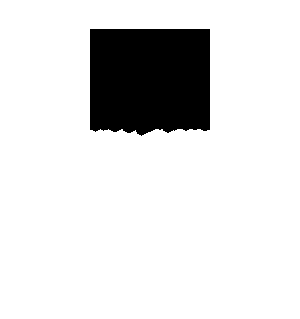


MorphedBW167 = sodaSegmenter(frame167);

imshow(~MorphedBW167)


nnz(~MorphedBW167)

ans = 13698

height = nnz(~MorphedBW167)/120

height = 114.1500

heightinCM = height*0.015

heightinCM = 1.7123

heightinCM

heightinCM = 1.7123